%%--------------------------------------------------------------------------------------------
%%  1. DDM fitting script
% Author: Liang Tong
% Date: 27/2/2025
%这里用的RTtime建模


%%
clc
clear
minRT = 0.15;% can't be faster
maxRT = 2.5;
cohlevels = [1.05 1.1 2.05 2.1];
% read the raw behavioural data in:
data =readtable([ 'TLb_ALL_ForR_exp2.csv'])

data = 6144×15 table
    subID    blocknum    contrast    muscle_used    perf        rt        evshowtime    respLR    corrLR    TiltSSVEP    EMG_onsite    EMGcountL    EMGcountR    EMGPtL     EMGPtR 
    _____    ________    ________    ___________    ____    __________    __________    ______    ______    _________    __________    _________    _________    _______    _______

      1         1          0.05           4          3      -0.0028953     0.81288        2         2       

%example=load('G:\My Drive\Phd\Stage1\BCPvsFDI\E1data_polit\Anlysis\Model fitting\Modeling_G2_exDots\data_allsubj.mat');
% col 1: subject num
% col 2: block num
% col 3: contrast (high or low contrast)
% col 4: muscle (4=FDI, 44=BCP)
% col 5: trial outcome (1=correct, 2=error, 4=no response, 3 too early, 6 slow, 5 wrong muscle)
% col 6: RT in sec
% col 7: evshowtime =[]   % 0.2sec additional time after response
% col 8: participant response, 1 = left, 2 = right 0= on response
% col 9: correct response, 1 = left, 2 = right
% col 10: first tilt used for SSVEP
% col11: EMGonsite time
data_arr= table2array(data);


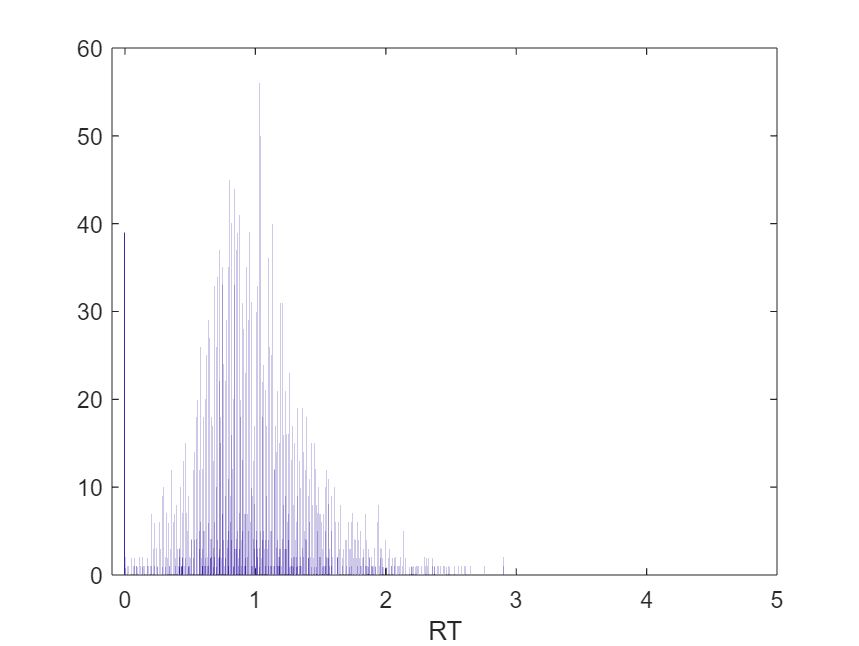

%%
% change to required format
% the behavioural data matrix should contain one row for each trial, and at least these 3 columns:
% col 1: condition (integers referring to different conditions. （1 = FDI_low，
% 2=FDI_high 3=BCP_Low 4=BCP_high)
% col 2: trial outcome (1=correct, 0=error, 2=miss if relevant)
% col 3: RT in sec (check it's not ms or EEG samples)

temp_condition=999*ones(size(data_arr,1),1);
temp_outcome=999*ones(size(data_arr,1),1);

for i=1: size(data_arr,1)

    %筛选条件 col 1
    if data_arr(i,3)==0.05 && data_arr(i,4)==4 % 4 is FDI
        temp_condition(i)=1;%1 = FDI_low
    elseif data_arr(i,3)==0.1 && data_arr(i,4)==4
        temp_condition(i)=2;%1 = FDI_high
    elseif data_arr(i,3)==0.05 && data_arr(i,4)==44
        temp_condition(i)=3;%1 = BCP_low
    elseif data_arr(i,3)==0.1 && data_arr(i,4)==44
        temp_condition(i)=4;%1 = BCP_high
    end

    %筛选结果对错和miss col 2
    if data_arr(i,8)==data_arr(i,9) && data_arr(i,5)~= 4 && data_arr(i,5)~= 3 && data_arr(i,5)~= 5
        temp_outcome(i)=1;%correct
    elseif data_arr(i,8)~=data_arr(i,9) && data_arr(i,5)~= 4 && data_arr(i,5)~= 3 && data_arr(i,5)~= 5
        temp_outcome(i)=0;%wrong
    elseif data_arr(i,5)== 4 ||data_arr(i,5)== 3||data_arr(i,5)== 5
        temp_outcome(i)=2;%miss
    end



end

data_allsubj(:,1)= temp_condition; %col 1: condition
data_allsubj(:,2)= temp_outcome; % col 2: trial outcome (1=correct, 0=error, 2=miss if relevant)
data_allsubj(:,3)= data_arr(:,6);% col 3: RT in sec (check it's not ms or EEG samples)
data_allsubj(:,4)=data_arr(:,1);% sub number

figure; hist(data_allsubj(:,3),[0:.001:5]); xlim([-0.1 5]); xlabel('RT') % note 1-ms resolution

If it's safe to count all early/wrong muscle to no response????/

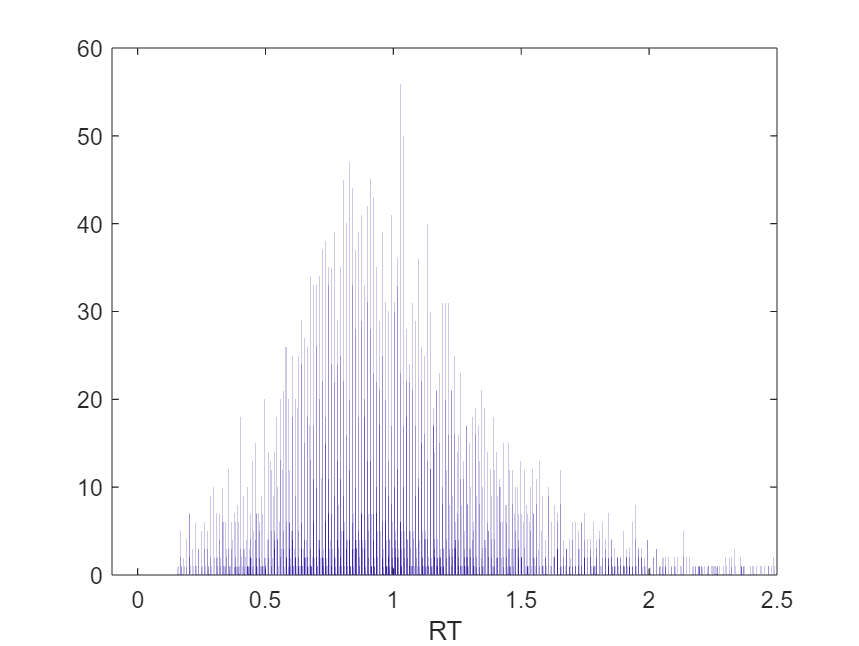

miss = find(data_allsubj(:,3)<0.15);
data_allsubj(miss,2)=2;
data_allsubj(miss,3)=nan;
figure; hist(data_allsubj(:,3),[0:.001:5]); xlim([-0.1 2.5]); xlabel('RT') % note 1-ms resolution

% Make the data summary:
% First define the RT quantiles from which we are going to compute the trial proportions for real and simulated data:
qps = [.1 .3 .5 .7 .9]; % these are quite standard
datsum = makeSummaryStructure(data_allsubj,qps,4); % the 4 indicates the column with a subject indicator, 

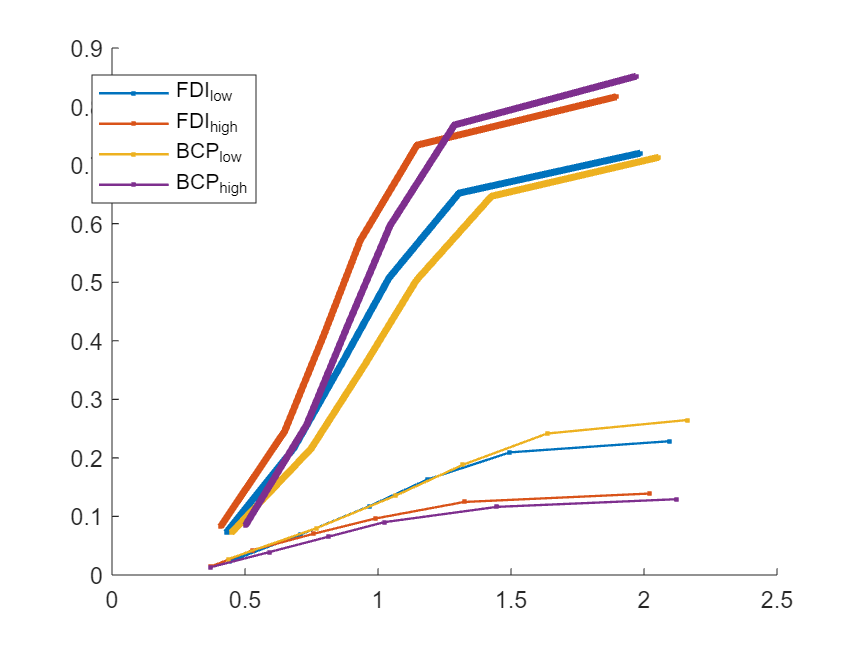

plotdatsum(datsum) % this plots a cumulative distribution, which makes it easy to see the effect of coheren e on RT and accuracy

above

%%%%% RTs are faster and the proportion correct relative to error are larger for higher coherences, as would be expected.

%%%BCP faster !!!!

 seed = sum(clock); % pick one rng seed and use it for ALL simulations to minimise the jittering about
% % let's just set one drift rate for the lowest coherence and let the function scale up the rest
% Sel = [1 1 0 0 0 1 1];  
% pm = [0.2 0.05 0 0 0 0.08 0]; % order: [tnd d(x4) b y]
% simdata = simul_2AFCddm(pm(Sel==1),pm(Sel==0),Sel,1000,seed);
% simdatsum = makeSummaryStructure(simdata,qps,0);
% plotdatsum(simdatsum)

% The full parameter vector pm for this model is as follows:
% tnd = nondecision time
% d(1) = drift rate for coherence level 1
% d(2) = drift rate for coherence level 2
% d(3) = drift rate for coherence level 3
% d(4) = drift rate for coherence level 4
% b = boundary height (separation = twice that) at time=0. UPPER BOUND IS CORRECT (convention)
% y = slope of bound collapse in units of /sec




% Define parameter ranges: 
par_range = [0 0.5;... % tnd 
            0 0.5;... % d(1) drift rate for lowest coherence
            0 0.5;... % d(2) drift rate for 2nd coherence
            0 0.5;... % d(3)
            0 0.5;... % d(4)
            0 0.5;... % b bound
            -0.25 0.5]; % y bound collapse slope - allowing it to increase over time, if that's what it needs to do to fit data


modelfn = 'simul_2AFCddm'; % name of function that will be called by G2 to generate predicted data
modelnames = {'ConstBnd_1d','ConstBnd_4d','CollBnd_1d','CollBnd_4d'};
% for each, designate which will be free to vary to fit data
Selvecs = {[1 1 0 0 0 1 0], [1 1 1 1 1 1 0], [1 1 0 0 0 1 1], [1 1 1 1 1 1 1]};
pm_if_fixed = [nan nan nan nan nan nan 0]; % order: [tnd d(x4) b y] any parameter that needs to be fixed at a certain value if not free to vary? Just y=0 for const bound
N=1000; % the more trials simulated per condition, the more accurate the G^2, AIC etc, and less specific to the happenstance of the particular noise generating by the rng. Keeping it relatively low for this tutorial so doesn't take all day
tic
for m=1:length(modelnames)
    disp(modelnames{m})
    Sel = Selvecs{m};
    options = optimoptions('particleswarm','UseParallel',true, 'SwarmSize', 10*sum(Sel));
    [p,g2(m)] = particleswarm(@(p) G2(p,pm_if_fixed(Sel==0),Sel,datsum,qps,modelfn,N,seed), sum(Sel), par_range((Sel==1),1)',par_range((Sel==1),2)', options);
    bestpm(m,Sel==1) = p; bestpm(m,Sel==0) = pm_if_fixed(Sel==0); 
    if all(Sel(2:5)==[1 0 0 0])
        % In the case of one free drift rate parameter,have to fill in the other drift rates:
        bestpm(m,3)=bestpm(m,2)*cohlevels(2)/cohlevels(1); bestpm(m,4)=bestpm(m,2)*cohlevels(3)/cohlevels(1); bestpm(m,5)=bestpm(m,2)*cohlevels(4)/cohlevels(1);
    end
    disp(['best parameters: ' num2str(bestpm(m,:))])
    numfreepm=sum(Sel);
    
    % Do a fresh simulation of many trials with new noise, for computing AIC/BIC:
    g2new(m) = G2(p,pm_if_fixed(Sel==0),Sel,datsum,qps,modelfn,20000,sum(clock)); % note fresh seed and 20,000 trials per condn
    AIC(m) = g2new(m) + 2*numfreepm;
    BIC(m) = g2new(m) + numfreepm*log(sum(datsum.n(:)));
end

ConstBnd_1d


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


best parameters: 0.36543    0.053525    0.056074      0.1045     0.10705     0.09054           0


ConstBnd_4d


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


best parameters: 0.37522    0.070953     0.11788    0.061604     0.11914    0.093155           0


CollBnd_1d


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


best parameters: 0.091824    0.050383    0.052783    0.098367     0.10077     0.15456    0.039868


CollBnd_4d


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


best parameters: 0.3316    0.066096     0.11073    0.060492    0.097375     0.10871    0.014683


toc % good to keep track of how long it takes, in case you want to explore ways of making it more efficient, e.g. increasing the step size, changing particleswarm settings

Elapsed time is 176.447081 seconds.


AIC

AIC =   190.6427  203.5170  272.2731  179.8690


BIC

BIC =   205.4371  233.1058  291.9990  214.3893


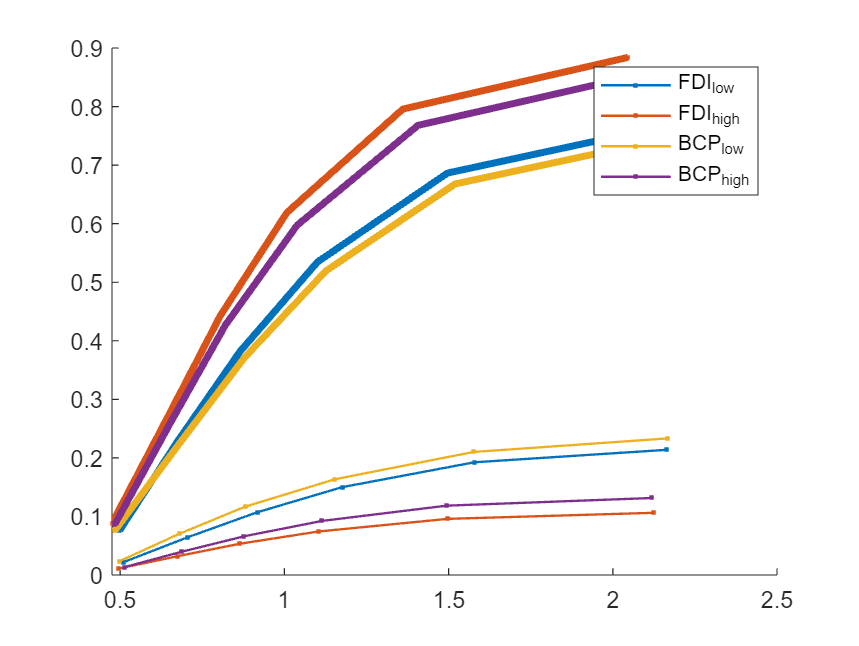

Sel = [1 1 1 1 1 1 1]; % the 4rd model has lowest AIC and BIC
simdata = simul_2AFCddm(bestpm(4,Sel==1),pm_if_fixed(Sel==0),Sel,10000,seed);
simdatsum = makeSummaryStructure(simdata,qps,0);
plotdatsum(simdatsum)

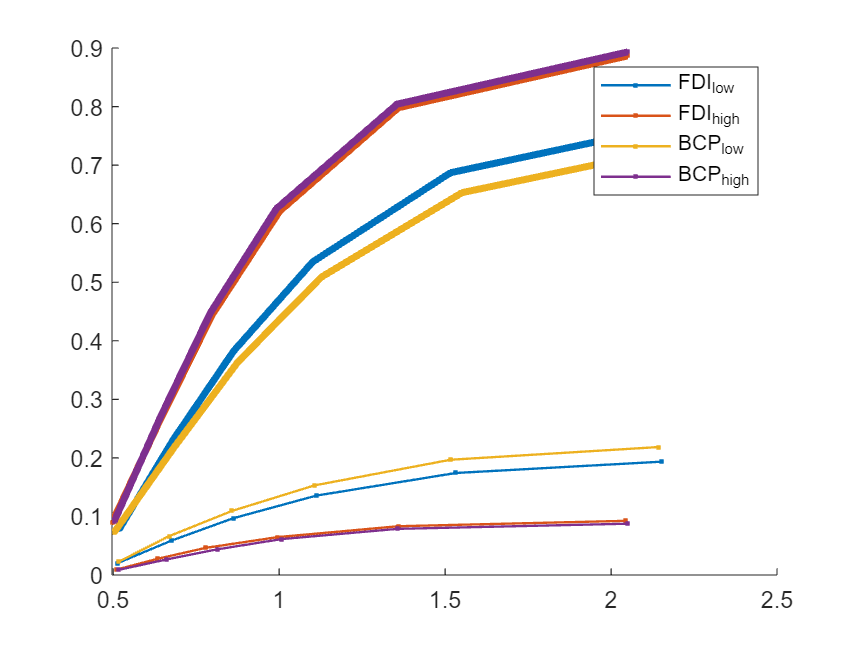

Sel = [1 1 0 0 0 1 0]; % the 1rd model has lowest AIC and BIC
simdata = simul_2AFCddm(bestpm(1,Sel==1),pm_if_fixed(Sel==0),Sel,10000,seed);
simdatsum = makeSummaryStructure(simdata,qps,0);
plotdatsum(simdatsum)